# Generalized System Response

Example 3: Matlab Solution. Find system response using system diagonalization. Uses system trabsformation and the symbolic toolbox function `expm` to solve:


$$\begin{array}{l}
{\bf{w}} = {{\rm T}^{ - 1}}{\bf{x}}\\
\Lambda  = {{\rm T}^{ - 1}}{\bf{AT}}\\
\frac{d}{{dt}}{\bf{w}} = \Lambda {\bf{w}} + {{\bf{T}}^{ - 1}}u
\end{array}$$


## Define state-space equations

A = [-3 -2
1 0];

B = [1
0];

x0 = [1 1]';

T = [1 1; -1 -1/2];

Tinv = inv(T);

## Modified state equations

Ax = Tinv*A*T

Ax =     -1     0
     0    -2


Bx = Tinv*B

Bx =     -1
     2


## Solve symbolically

syms s t
phi(t) = expm(Ax*t)

$$phi(t) = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & 0\\ 0 & {\mathrm{e}}^{-2\,t} \end{array}\right)$$

w0 = Tinv*x0

w0 =     -3
     4


## Initial condition response

w1 = phi(t)*w0

$$w1 = \left(\begin{array}{c} -3\,{\mathrm{e}}^{-t}\\ 4\,{\mathrm{e}}^{-2\,t} \end{array}\right)$$

## Forced response

w2 = int(phi(t-tau)*Bx,tau,0,t)

$$w2 = \left(\begin{array}{c} {\mathrm{e}}^{-t}-1\\ 1-{\mathrm{e}}^{-2\,t} \end{array}\right)$$

## Total response

w = w1 + w2

$$w = \left(\begin{array}{c} -2\,{\mathrm{e}}^{-t}-1\\ 3\,{\mathrm{e}}^{-2\,t}+1 \end{array}\right)$$

## System response

Since:


$${\mathbf{x}} = {\mathbf{Tw}}$$


x = T*w

$$x = \left(\begin{array}{c} 3\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t}\\ 2\,{\mathrm{e}}^{-t}-\frac{3\,{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{2} \end{array}\right)$$

## Print it nicely

for m-file only!

pretty(x)

/   exp(-2 t) 3 - 2 exp(-t)   \
|                             |
|             exp(-2 t) 3   1 |
| 2 exp(-t) - ----------- + - |
\                  2        2 /



## Plot response

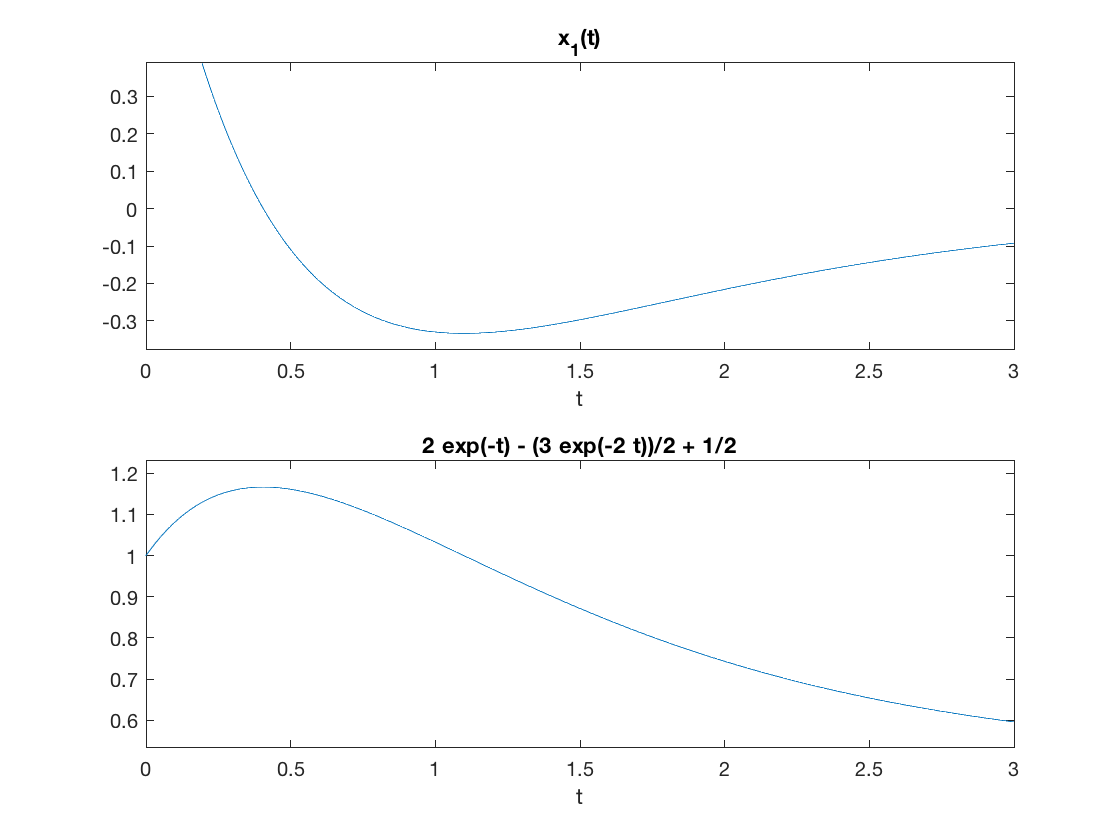

subplot(211)
ezplot(x(1),[0,3])
title('x_1(t)')
subplot(212)
title('x_2(t)')
ezplot(x(2),[0,3])